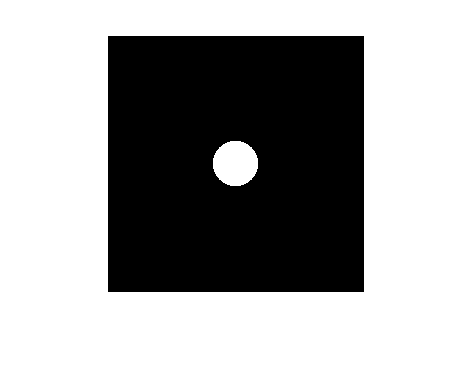

img = imread('Important_files/cameraman.tif');

dft = fftshift(fft2(img));
D0 = 1/8 * sqrt(2*128^2);
[rows,cols] = size(dft);
maxu = cols/2;
maxv = rows/2;
u = linspace(1, 2*maxu, 2*maxu) - maxu;
v = linspace(1, 2*maxv, 2*maxv) - maxv;
[uu,vv] = meshgrid(u,v);
filter = (sqrt(uu.^2 + vv.^2) <= D0);
imshow(filter, [])

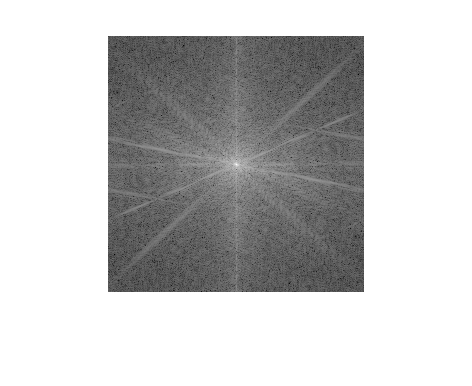


filter_high_pass = 1 - filter;

filtered = filter.*dft;
filtered_high_pass = filter_high_pass.*dft;

imshow(log(abs(dft)), [])

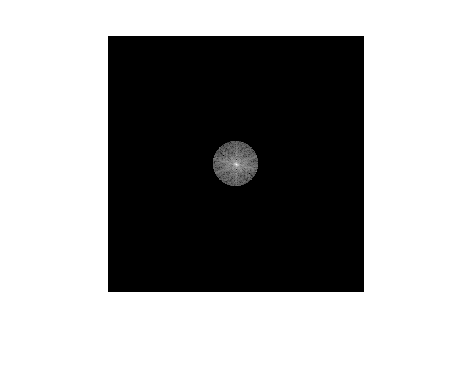

imshow(log(abs(filtered)), [])

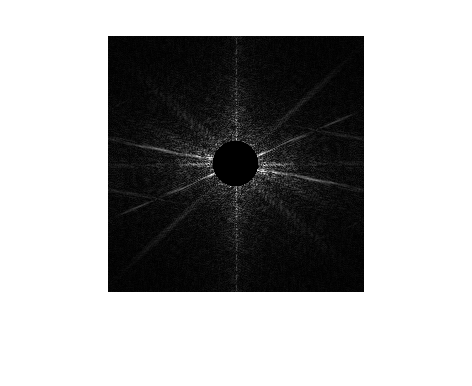

imshow(abs(dft-filtered),[])

imshow(abs(filtered_high_pass),[])

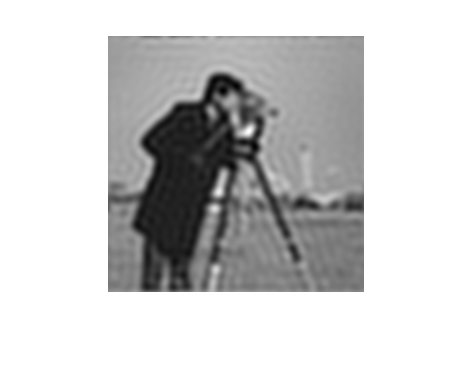


filtered_spatial = real(ifft2(fftshift(filtered)));
filter_spatial = fftshift(ifft2(filter));

filtered_high_pass_spatial = real(ifft2(fftshift(filtered_high_pass)));
filter_spatial_hp = fftshift(ifft2(filter_high_pass));

imshow(filtered_spatial, [])

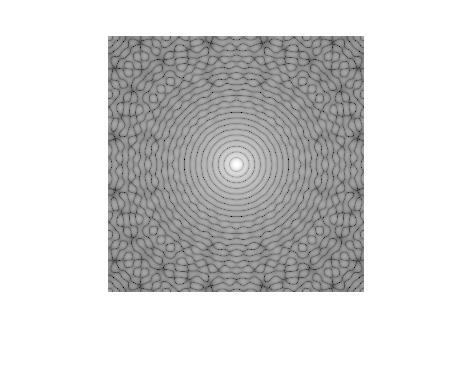

imshow(real(log(filter_spatial)), [])

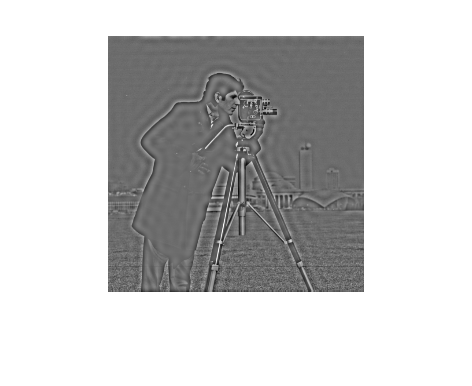

imshow(filtered_high_pass_spatial, [])

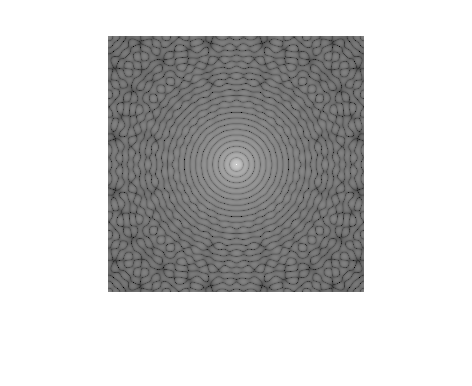

imshow(real(log(filter_spatial_hp)), [])

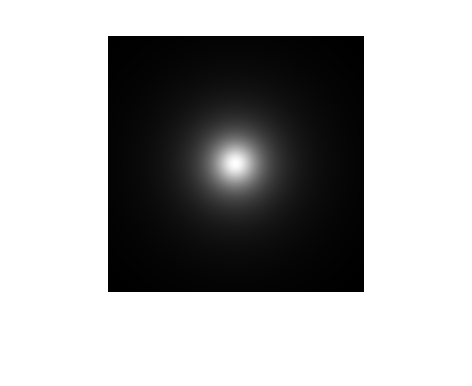

n=1;

filter_b = (1./(1 + (sqrt(uu.^2 + vv.^2)./D0).^(2*n)));
filter_b_hp = 1 - filter_b;
imshow(filter_b, []);

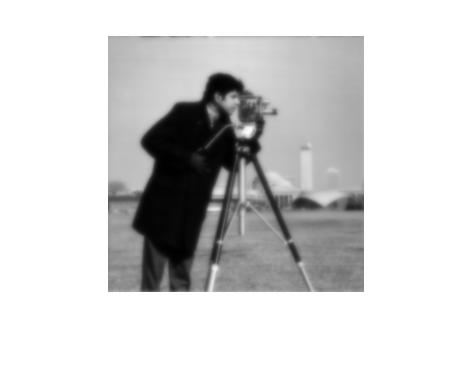

filtered_b = filter_b.*dft;
filtered_b_hp = filter_b_hp.*dft;

filtered_b_spatial = real(ifft2(fftshift(filtered_b)));
filtered_b_hp_spatial = real(ifft2(fftshift(filtered_b_hp)));
imshow(filtered_b_spatial, [])

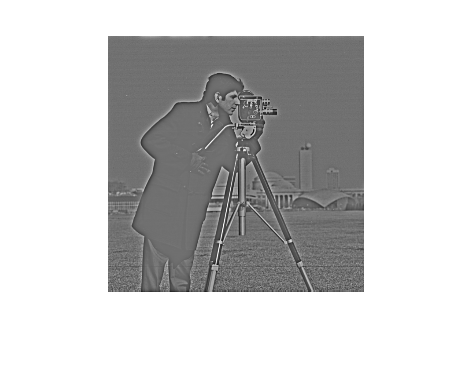

imshow(filtered_b_hp_spatial, [])

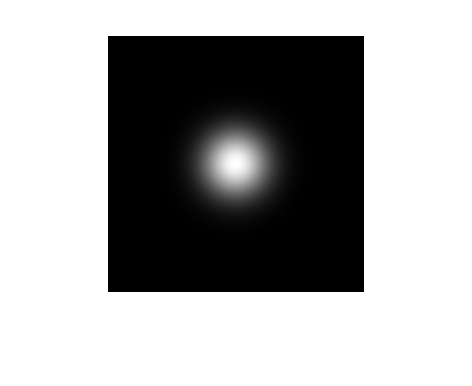

filter_g = (exp(-(uu.^2 + vv.^2)./(2*D0^2)));
filter_g_hp = 1 - filter_g;
imshow(filter_g, []);

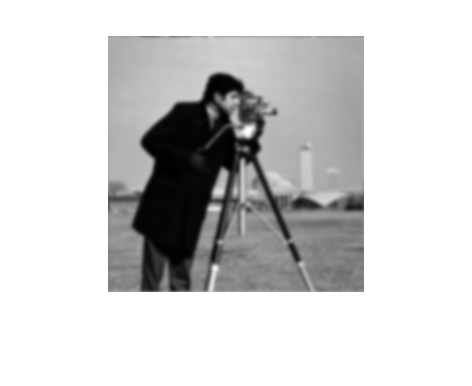

filtered_g = filter_g.*dft;
filtered_g_hp = filter_g_hp.*dft;

filtered_g_spatial = real(ifft2(fftshift(filtered_g)));
filtered_g_hp_spatial = real(ifft2(fftshift(filtered_g_hp)));
imshow(filtered_g_spatial, [])

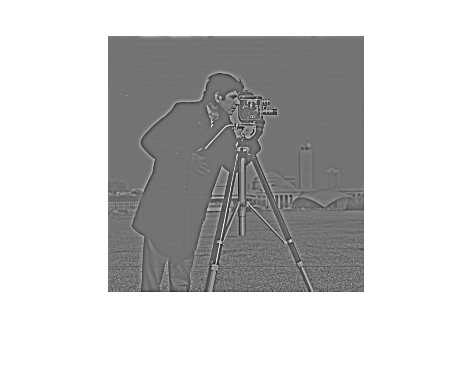

imshow(filtered_g_hp_spatial, [])

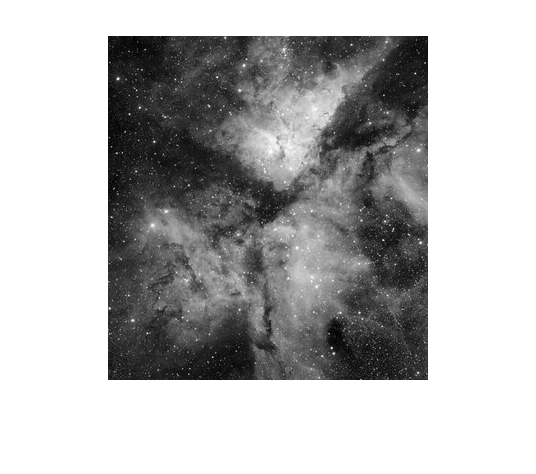

space_img = imread('Important_files/eso1250a.jpeg');
space_img = rgb2gray(space_img);

imshow(space_img);

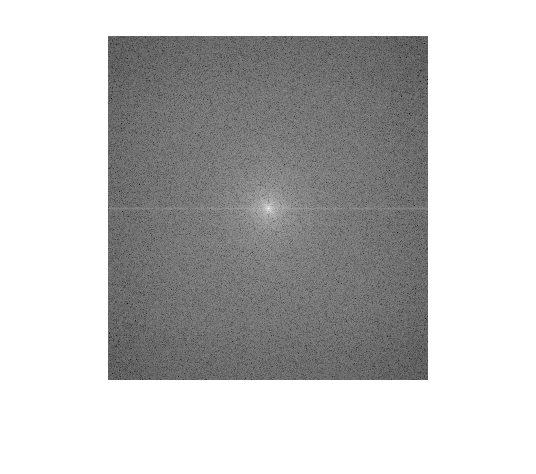


space_dft = fftshift(fft2(space_img));
imshow(log(abs(space_dft)), []);

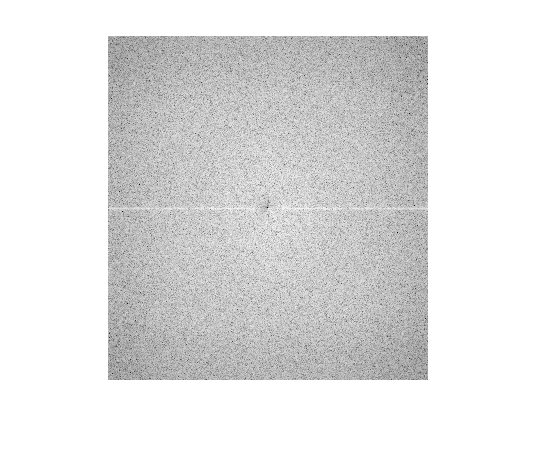



[rows,cols] = size(space_dft);
maxu = cols/2;
maxv = rows/2;
u = linspace(1, 2*maxu, 2*maxu) - maxu;
v = linspace(1, 2*maxv, 2*maxv) - maxv;
[uu,vv] = meshgrid(u,v);
D0 = 1/8 * sqrt(2*maxu^2);
n = 1;
%g = (sqrt(uu.^2 + vv.^2) <= D0);
g = (1./(1 + (sqrt(uu.^2 + vv.^2)./D0).^(2*n)));
g_hp = 1 - g;

ideal = g_hp.*space_dft;

imshow(log(abs(ideal)), []);

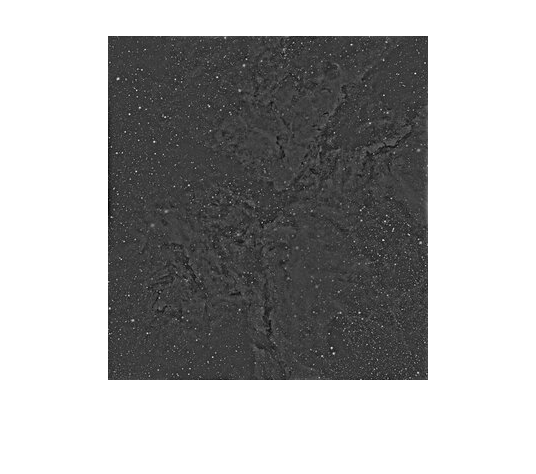


ideal_spatial = real(ifft2(fftshift(ideal)));

imshow(ideal_spatial, [])

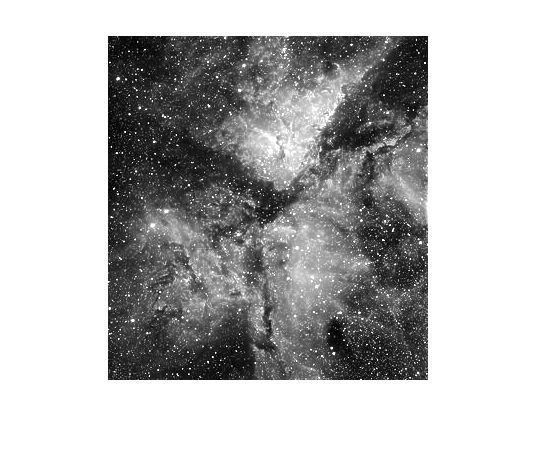


A = 2;

imshow(space_img + A * uint8(ideal_spatial));